# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

% use our trained classifiers to classify the testing data:
[predictions_nb, scores_nb] = predict(m_nb, test_examples);
[predictions_dt, scores_dt] = predict(m_dt, test_examples);

% output a confusion matrix:
[c_nb,order_nb] = confusionmat(test_labels, predictions_nb)

c_nb =     83     2
     4    53


order_nb = 2×1 categorical array
     Benign 
     Malignant 


[c_dt,order_dt] = confusionmat(test_labels, predictions_dt)

c_dt =     82     3
     5    52


order_dt = 2×1 categorical array
     Benign 
     Malignant 



% TPR
tpr_nb = c_nb(end, end) / sum(c_nb(end, 1:end))

tpr_nb = 0.9298

tpr_dt = c_dt(end, end) / sum(c_dt(end, 1:end))

tpr_dt = 0.9123


% FPR
fpr_nb = c_nb(1, end) / sum(c_nb(1, 1:end))

fpr_nb = 0.0235

fpr_dt = c_dt(1, end) / sum(c_dt(1, 1:end))

fpr_dt = 0.0353


% ROC
% plot(fpr_nb, tpr_nb)
[perf_nb_y, perf_nb_x] = perfcurve(test_labels,scores_nb(1:end, end),'Benign')

perf_nb_y =          0
    0.7895
    0.8070
    0.8246
    0.8421
    0.8596
    0.8772
    0.8947
    0.9123
    0.9123


perf_nb_x =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0118


[perf_dt_y, perf_dt_x] = perfcurve(test_labels,scores_dt(1:end, end),'Benign')

perf_dt_y =          0
    0.8947
    0.9123
    0.9123
    1.0000


perf_dt_x =          0
    0.0118
    0.0353
    0.0471
    1.0000


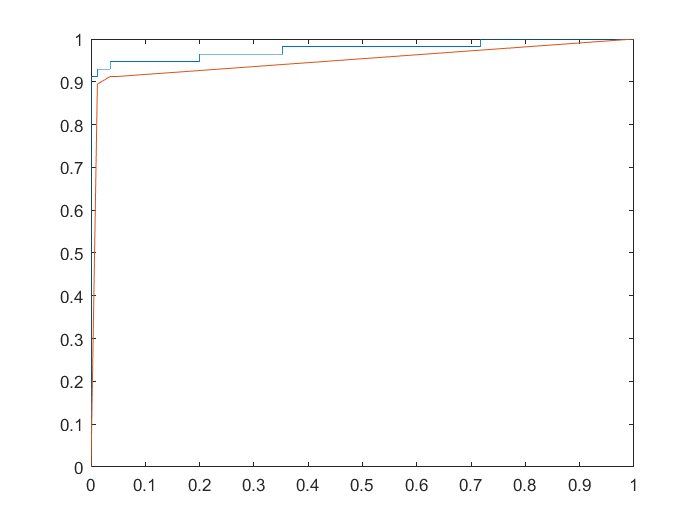

plot(perf_nb_x, perf_nb_y, perf_dt_x, perf_dt_y)